addpath(genpath('C:\Users\Yoon Sunmoon\Desktop\uBD\Data'));
addpath(genpath('C:\Users\Yoon Sunmoon\Desktop\uBD\ULDP scheme'));

1) Style Settings

Configure default fonts, interpreters, and sizes for consistent figure appearance

clear; clc;
set(groot, 'defaultTextInterpreter',              'latex');
set(groot, 'defaultAxesTickLabelInterpreter',     'latex');
set(groot, 'defaultLegendInterpreter',            'latex');
set(groot, 'defaultColorbarTickLabelInterpreter', 'latex');
set(groot, 'defaultAxesFontName',    'Computer Modern');
set(groot, 'defaultTextFontName',    'Computer Modern');
set(groot, 'defaultLegendFontName',  'Computer Modern');
set(groot, 'defaultAxesFontSize',    12);
set(groot, 'defaultTextFontSize',    12);
set(groot, 'defaultLegendFontSize',  12);

2) Load Data

Import MSE results for different mechanisms and prepare plotting parameters

fname : 'MSE_and_R50000_m20.mat' or 'MSE_or_R50000_m20.mat'

fname = 'MSE_or_R50000_m20.mat';
D = load(fname, ...
     'epsRange','nPts', ...
     'mse_uRR','mse_uRAP','mse_uOUE','mse_uHR','mse_opt','mse_noPriv');

epsRange = D.epsRange;   % 3 × 2 array of epsilon ranges
nPts     = D.nPts;
mseAll   = {D.mse_uRR, D.mse_uRAP, D.mse_uOUE, D.mse_uHR, D.mse_opt};
y_np     = mean(D.mse_noPriv, 2);   % mean of non-private baseline, 3 × 1

labels    = {'uRR','uRAP','uOUE','uHR','Proposed'};
markers   = {'o','s','^','d','p'};
colors    = lines(numel(labels));
markerIdx = round(linspace(1, nPts, 10));
alphaBand = 0.1;

% Pre-allocate handles for legend (taken from the first figure only)
hPlots = gobjects(numel(labels),1);

3) Plot Results per Segment

Generate three separate figures corresponding to different epsilon ranges

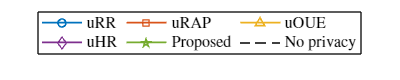

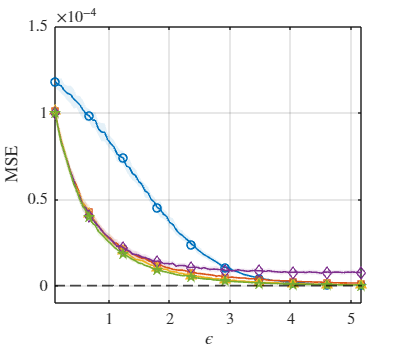

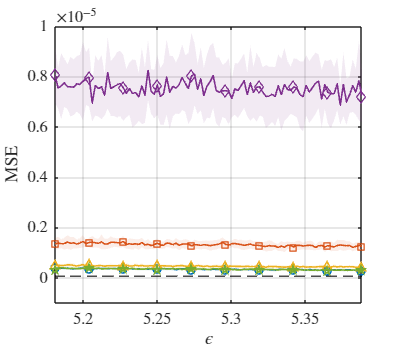

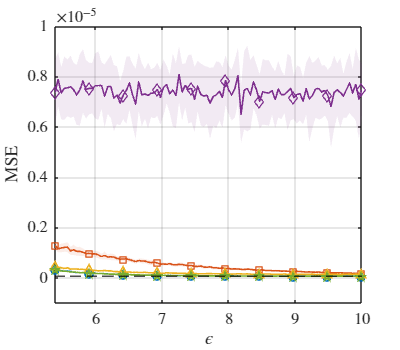

for sFig = 1:4
    % Legend only figure
    if sFig == 1
        figLeg = figure(1);
        figLeg.Position = [100 100 400 80];
        clf(figLeg);
        ax = axes(figLeg, 'Visible','off'); 
        hold(ax,'on');

        dummy = gobjects(numel(labels)+1,1);
        for i = 1:numel(labels)
        dummy(i) = plot(ax, NaN,NaN, 'LineWidth',1.2, ...
            'Marker', markers{i}, 'Color', colors(i, :),...
            'DisplayName', labels{i}); 
        end
        dummy(end) = plot(ax, NaN,NaN, '--k', 'DisplayName','No privacy');

        legend(ax, dummy, 'Orientation','horizontal', ...
            'Location','northoutside', 'FontSize',12, 'Box','on','NumColumns',3);
        ax.Visible = 'off';

    else
        seg = sFig - 1;
        fig = figure(sFig+1);
        fig.Position  = [100 100 400 350];
        clf(fig);
        hold on; grid on; box on;
    
        x = linspace(epsRange(seg,1), epsRange(seg,2), nPts);
    
        for i = 1:numel(labels)
            y   = squeeze(mean(mseAll{i}(seg,:,:), 3));
            err = squeeze(std(mseAll{i}(seg,:,:), 0, 3));
        
            % Error band (mean ± std)
            x2 = [x, fliplr(x)];
            y2 = [y+err, fliplr(y-err)];
            fill(x2, y2, colors(i,:), ...
                'FaceAlpha', alphaBand, ...
                'EdgeColor', 'none', ...
                'HandleVisibility','off');
        
            % Mean curve with markers
            semilogy(x, y, ...
                'Color',           colors(i,:), ...
                'Marker',          markers{i}, ...
                'MarkerIndices',   markerIdx, ...
                'LineWidth',       1.2, ...
                'MarkerSize',      6, ...
                'DisplayName',     labels{i});
        end

        % Non-private baseline
        yline(y_np(seg), '--k', 'LineWidth',1.2, 'HandleVisibility','off');
        
        %% Axis settings for each segment
        % Define y-limits and exponent values in one place
        if contains(fname, '_and_')
            axisSettings = struct( ...
            'ylim', {[-1e-5, 2.8e-4], [0, 1e-6], [0.5e-7, 3e-7]}, ...
            'exp',  {-4, -6, -7} ...
            );
        else
            
            axisSettings = struct( ...
                'ylim', {[-1e-5, 1.5e-4], [-1e-6, 1e-5], [-1e-6, 1e-5]}, ...  % <- adjust if you like
                'exp',  {-4, -5, -5} ...
            );
        end

        % Apply axis settings
        ylim(axisSettings(seg).ylim);
        ax = gca;
        ax.YAxis.Exponent = axisSettings(seg).exp;
    
        xlim([epsRange(seg,1), epsRange(seg,2)]);
        xlabel('$\epsilon$', 'Interpreter','latex');
        ylabel('MSE',       'Interpreter','latex');
    
        hold off;
    end
end